## **概率论与数理统计项目1-产品质量管理**

### **date：2025/4/29 21:30         Writer：王子诺 20235459（Interstellar～兮儿）**

**本项目数据来源为随机生成的正态数据，按照以下项目要求进行编写：**

· 首先收集实际数据或者用软件生成模拟数据，要求25组以上，每组至少5个以上样本；

· 数据描述性统计分析：均值，方差，极差，直方图等等指标；

· 数据正态性检验，以及总体均值检验；

· 数据工序能力指数计算和评估；

· 均值控制图和方差控制图描绘。

· 作结论：工艺水平如何；生产过程是否处于统计受控状态。

### 一、生成数据

生成25组正态分布数据，每组300个样本，使用均值设置为80，方差设置为1（以上参数均可调整）

num_groups = 25; % 组数
samples_per_group = 300; % 每组样本数

mu = 80; % 正态分布均值
sigma = 1; % 正态分布标准差

% 初始化数据存储矩阵
data = zeros(num_groups, samples_per_group);

% 生成正态分布数据
for i = 1:num_groups
    data(i, :) = normrnd(mu, sigma, [1, samples_per_group]);
end

二、计算各样本的均值、方差、极差，并绘制条形图、箱线图

% 初始化结果存储
means = zeros(1, size(data, 1)); % 每组均值
variances = zeros(1, size(data, 1)); % 每组方差
ranges = zeros(1, size(data, 1)); % 每组极差

% 计算每组的均值、方差和极差
for i = 1:size(data, 1)
    means(i) = mean(data(i, :)); % 均值
    variances(i) = var(data(i, :)); % 方差
    ranges(i) = max(data(i, :)) - min(data(i, :)); % 极差
end

% 创建表格显示结果
group_numbers = (1:size(data, 1))'; % 组号
stats_table = table(group_numbers, means', variances', ranges', ...
    'VariableNames', {'组号', '均值', '方差', '极差'});

% 显示表格
disp('每组的统计结果：');

每组的统计结果：


disp(stats_table);

    组号     均值      方差       极差 
    ____    ______    _______    ______

      1     79.968    0.85013    5.0093
      2     80.123     1.0927    5.8302
      3     79.915     1.0536    5.4544
      4     79.949     1.0203    5.3222
      5     80.037     0.9128    5.6505
      6     79.995    0.94838    6.2022
      7     79.999    0.94175    5.6814
      8     80.009    0.93347    6.7833
      9     80.014     1.1096    6.4218
     10      80.05    0.95076     5.193
     11     80.003     1.0417    5.9632
     12     80.019     1.0087    6.3087
     13     79.911     1.1064     5.794
     14     79.985    0.94057    5.6233
     15     80.043     1.0536    5.0876
     16     79.962     1.0319    6.1055
     17     79.955    0.94689    5.8052
     18     80.101    0.93417    4.7546
     19      79.93     1.0543     5.966
     20     79.937    0.90776    4.9928
     21     80.032     1.0272    5.8447
     22     79.912     1.0584     6.641
     23     79.886    0.83387    5.0402
     24

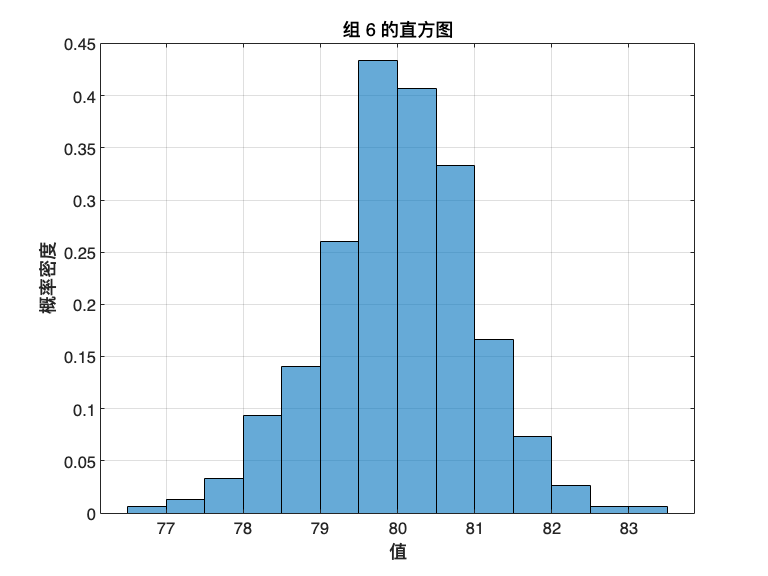


% 随机抽取一组
num_groups = size(data, 1);
random_group_idx = randi(num_groups); % 随机选择一组的索引
selected_data = data(random_group_idx, :); % 提取该组数据

% 绘制直方图

histogram(selected_data, 'Normalization', 'pdf', 'BinWidth', 0.5);
title(sprintf('组 %d 的直方图', random_group_idx));
xlabel('值');
ylabel('概率密度');
grid on;

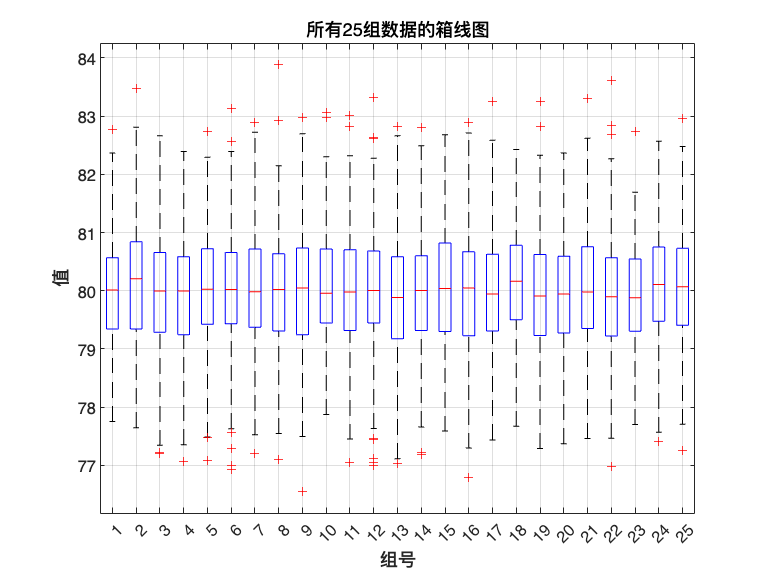

% 绘制所有组的箱线图（右侧）
boxplot(data', 'Labels', string(1:num_groups));
title('所有25组数据的箱线图');
xlabel('组号');
ylabel('值');
grid on;
set(gca, 'XTickLabelRotation', 45); % 旋转X轴标签以避免重叠

### 三、正态检验

由于数据本身是正态分布随机生成，先添加噪声再进行检验

以下提供三种噪声供选择性添加

注：若添加高斯噪声，可能对数据分布类型没有很大的改变

% % 添加高斯噪声
% noise_mu = 0;
% noise_sigma = 25;
% noise = normrnd(noise_mu, noise_sigma, size(data));
% noisy_data = data + noise;

%添加均匀分布噪声
noise_min = -10; % 噪声范围下界
noise_max = 10;  % 噪声范围上界
noise = noise_min + (noise_max - noise_min) * rand(size(data));
noisy_data = data + noise;

%添加泊松分布噪声
% lambda = 10; % 泊松分布的均值
% noise = poissrnd(lambda, size(data));
% noisy_data = data + noise;

然后进行K-s检验（非假设参数检验）

% 初始化参数
num_groups = size(noisy_data, 1);
test_mean = mu; % 检验的理论均值（与数据生成过程的 mu 一致）
alpha = 0.05; % 显著性水平

% 初始化结果存储
p_values_ttest = zeros(num_groups, 1); % 均值检验 p 值
h_values_ttest = zeros(num_groups, 1); % 均值检验结果（1=拒绝均值等于 test_mean，0=接受）
sample_means = zeros(num_groups, 1); % 每组样本均值
p_values_ks = zeros(num_groups, 1); % KS 正态性检验 p 值
h_values_ks = zeros(num_groups, 1); % KS 正态性检验结果（1=拒绝正态性，0=接受）

% 对每组进行 KS 正态性检验和单样本 t 检验
for i = 1:num_groups
    % KS 正态性检验
    data_standardized = (noisy_data(i, :) - mean(noisy_data(i, :))) / std(noisy_data(i, :));
    [h_values_ks(i), p_values_ks(i)] = kstest(data_standardized);
    if p_values_ks(i) >= alpha
        h_values_ks(i) = 0; % 接受正态性假设
    else
        h_values_ks(i) = 1; % 拒绝正态性假设
    end
    
    % 单样本 t 检验
    [h_values_ttest(i), p_values_ttest(i)] = ttest(noisy_data(i, :), test_mean, 'Alpha', alpha);
    sample_means(i) = mean(noisy_data(i, :));
    
    % 输出每组正态性检验结果
    result = '接受';
    if h_values_ks(i) == 1
        result = '拒绝';
    end
    fprintf('组 %d: 正态性 p值 = %.4f, %s正态分布 (H=%d); 均值检验 p值 = %.4f, H=%d\n', ...
            i, p_values_ks(i), result, h_values_ks(i), p_values_ttest(i), h_values_ttest(i));
end

组 1: 正态性 p值 = 0.1129, 接受正态分布 (H=0); 均值检验 p值 = 0.8053, H=0
组 2: 正态性 p值 = 0.0807, 接受正态分布 (H=0); 均值检验 p值 = 0.8854, H=0
组 3: 正态性 p值 = 0.0242, 拒绝正态分布 (H=1); 均值检验 p值 = 0.6919, H=0
组 4: 正态性 p值 = 0.0433, 拒绝正态分布 (H=1); 均值检验 p值 = 0.2372, H=0
组 5: 正态性 p值 = 0.0657, 接受正态分布 (H=0); 均值检验 p值 = 0.4575, H=0
组 6: 正态性 p值 = 0.2041, 接受正态分布 (H=0); 均值检验 p值 = 0.0789, H=0
组 7: 正态性 p值 = 0.1109, 接受正态分布 (H=0); 均值检验 p值 = 0.2312, H=0
组 8: 正态性 p值 = 0.0214, 拒绝正态分布 (H=1); 均值检验 p值 = 0.3568, H=0
组 9: 正态性 p值 = 0.2850, 接受正态分布 (H=0); 均值检验 p值 = 0.8102, H=0
组 10: 正态性 p值 = 0.2741, 接受正态分布 (H=0); 均值检验 p值 = 0.9970, H=0
组 11: 正态性 p值 = 0.0266, 拒绝正态分布 (H=1); 均值检验 p值 = 0.6953, H=0
组 12: 正态性 p值 = 0.0543, 接受正态分布 (H=0); 均值检验 p值 = 0.1909, H=0
组 13: 正态性 p值 = 0.0730, 接受正态分布 (H=0); 均值检验 p值 = 0.2026, H=0
组 14: 正态性 p值 = 0.2054, 接受正态分布 (H=0); 均值检验 p值 = 0.9064, H=0
组 15: 正态性 p值 = 0.2217, 接受正态分布 (H=0); 均值检验 p值 = 0.9872, H=0
组 16: 正态性 p值 = 0.1014, 接受正态分布 (H=0); 均值检验 p值 = 0.2064, H=0
组 17: 正态性 p值 = 0.0875, 接受正态分布 (H=0); 均值检验 p值 = 0.7136, H=0
组 18: 

% 总结正态性检验结果
num_accepted = sum(h_values_ks == 0);
fprintf('\n总结：在显著性水平 %.2f 下：\n', alpha);


总结：在显著性水平 0.05 下：


fprintf('%d 组接受正态分布假设，%d 组拒绝正态分布假设。\n', ...
        num_accepted, num_groups - num_accepted);

17 组接受正态分布假设，8 组拒绝正态分布假设。


*Question1：为什么正态检验总是高于显著性水平？*

*Answer1:因为添加的高斯噪声也是正态分布，因此合成后数据任服从正态分布。*

4、总体均值检验（对通过正态检验的组进行总体均值检验，即进行假设参数检验）

% 对通过正态性检验的组进行总体均值检验
normal_groups = find(h_values_ks == 0);
if isempty(normal_groups)
    fprintf('没有组通过正态性检验，无法进行总体均值检验。\n');
else
    % 合并通过正态检验的组的数据
    normal_data = noisy_data(normal_groups, :);
    normal_data = normal_data(:); % 展平数据
    
    % 总体均值检验
    [h_normal_all, p_normal_all] = ttest(normal_data, test_mean, 'Alpha', alpha);
    mean_normal_all = mean(normal_data);
    
    % 显示总体均值检验结果
    fprintf('\n通过正态检验的组（组号：%s）：\n', num2str(normal_groups'));
    fprintf('样本均值 = %.4f, p值 = %.4f, H = %d\n', mean_normal_all, p_normal_all, h_normal_all);
    if h_normal_all == 0
        fprintf('接受总体均值等于 %.2f 的假设\n', test_mean);
    else
        fprintf('拒绝总体均值等于 %.2f 的假设\n', test_mean);
    end
end


通过正态检验的组（组号：1   2   5   6   7   9  10  12  13  14  15  16  17  18  20  21  24）：


样本均值 = 80.0167, p值 = 0.8374, H = 0


接受总体均值等于 80.00 的假设



% 对所有数据进行总体均值检验
all_data = noisy_data(:); % 展平所有数据
[h_all, p_all] = ttest(all_data, test_mean, 'Alpha', alpha);
mean_all = mean(all_data);
fprintf('\n所有数据的总体均值检验结果：\n');


所有数据的总体均值检验结果：


fprintf('样本均值 = %.4f, p值 = %.4f, H = %d\n', mean_all, p_all, h_all);

样本均值 = 79.9116, p值 = 0.1914, H = 0


if h_all == 0
    fprintf('接受总体均值等于 %.2f 的假设\n', test_mean);
else
    fprintf('拒绝总体均值等于 %.2f 的假设\n', test_mean);
end

接受总体均值等于 80.00 的假设



% 创建表格展示每组结果
group_numbers = (1:num_groups)';
stats_table = table(group_numbers, sample_means, p_values_ttest, h_values_ttest, p_values_ks, h_values_ks, ...
    'VariableNames', {'组号', '样本均值', '均值检验p值', '均值检验H值', '正态性p值', '正态性H值'});
disp('每组的检验结果：');

每组的检验结果：


disp(stats_table);

    组号    样本均值    均值检验p值    均值检验H值    正态性p值    正态性H值
    ____    _______    __________    __________    ________    ________

      1     79.917         0.8053        0          0.11287       0    
      2     80.051        0.88539        0          0.08072       0    
      3     79.862        0.69194        0         0.024224       1    
      4     79.608        0.23715        0         0.043337       1    
      5     79.743        0.45751        0         0.065652       0    
      6     80.557       0.078884        0          0.20406       0    
      7     79.602        0.23119        0          0.11094       0    
      8     79.678        0.35684        0         0.021435       1    
      9     79.921        0.81018        0          0.28495       0    
     10     79.999        0.99702        0          0.27414       0    
     11     80.141        0.69525        0         0.026625       1    
     12     80.448        0.19095        0         0.054305       0    
     13   

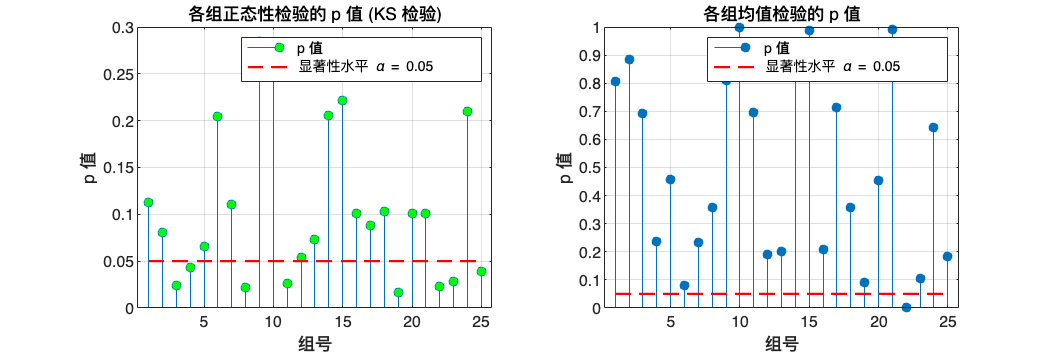


% 可视化 p 值分布
figure('Position', [100, 100, 1200, 400]);
% 正态性检验 p 值
subplot(1, 2, 1);
stem(1:num_groups, p_values_ks, 'filled', 'MarkerFaceColor', 'g');
hold on;
plot([1, num_groups], [alpha, alpha], 'r--', 'LineWidth', 1.5);
title('各组正态性检验的 p 值 (KS 检验)');
xlabel('组号');
ylabel('p 值');
grid on;
legend('p 值', sprintf('显著性水平 \\alpha = %.2f', alpha));
hold off;

% 均值检验 p 值
subplot(1, 2, 2);
stem(1:num_groups, p_values_ttest, 'filled');
hold on;
plot([1, num_groups], [alpha, alpha], 'r--', 'LineWidth', 1.5);
title('各组均值检验的 p 值');
xlabel('组号');
ylabel('p 值');
grid on;
legend('p 值', sprintf('显著性水平 \\alpha = %.2f', alpha));
hold off;

### 四、产品工序能力指数（使用6sigma)

上下规范值T_U,T_L是已知的产品加工要求，在代码中表现为USL和LSL，需要根据实际行业规定进行调整

% 初始化参数
num_groups = size(noisy_data, 1);
USL = 150; % 规格上限
LSL = -150; % 规格下限
cpk_values = zeros(num_groups, 1); % 存储Cpk值
sample_means = zeros(num_groups, 1); % 样本均值
sample_stds = zeros(num_groups, 1); % 样本标准差

% 计算每组的Cpk
for i = 1:num_groups
    sample_means(i) = mean(noisy_data(i, :));
    sample_stds(i) = std(noisy_data(i, :));
    % 计算Cpk
    cpk_upper = (USL - sample_means(i)) / (3 * sample_stds(i)); % 上限能力
    cpk_lower = (sample_means(i) - LSL) / (3 * sample_stds(i)); % 下限能力
    cpk_values(i) = min(cpk_upper, cpk_lower); % 取最小值
end

% 创建表格展示结果
group_numbers = (1:num_groups)';
stats_table = table(group_numbers, sample_means, sample_stds, cpk_values, ...
    'VariableNames', {'组号', '样本均值', '样本标准差', 'Cpk'});

% 显示结果
disp('每组的Cpk计算结果：');

每组的Cpk计算结果：


disp(stats_table);

    组号    样本均值    样本标准差     Cpk  
    ____    _______    _________    ______

      1     79.917      5.8154      4.0171
      2     80.051      6.1324      3.8021
      3     79.862      6.0225       3.882
      4     79.608      5.7247      4.0987
      5     79.743      5.9923      3.9082
      6     80.557      5.4667      4.2344
      7     79.602      5.7477      4.0827
      8     79.678       6.045      3.8777
      9     79.921      5.6926      4.1035
     10     79.999      5.7704      4.0437
     11     80.141      6.2083      3.7508
     12     80.448      5.9138      3.9203
     13     79.566      5.8816      3.9918
     14     80.039      5.7663      4.0443
     15     80.005      5.8426      3.9934
     16     80.409      5.5903      4.1495
     17      80.12      5.6747      4.1048
     18     80.316      5.9458      3.9066
     19     79.424      5.8931       3.992
     20     79.744      5.9423      3.9411
     21     80.003      5.8251      4.0055
     22     78.866 

% 评估Cpk
disp('Cpk评估：');

Cpk评估：


for i = 1:num_groups
    if cpk_values(i) >= 1.33
        assessment = '优秀';
    elseif cpk_values(i) >= 1.0
        assessment = '合格';
    else
        assessment = '不足';
    end
    fprintf('组 %d: Cpk = %.4f (%s)\n', i, cpk_values(i), assessment);
end

组 1: Cpk = 4.0171 (优秀)
组 2: Cpk = 3.8021 (优秀)
组 3: Cpk = 3.8820 (优秀)
组 4: Cpk = 4.0987 (优秀)
组 5: Cpk = 3.9082 (优秀)
组 6: Cpk = 4.2344 (优秀)
组 7: Cpk = 4.0827 (优秀)
组 8: Cpk = 3.8777 (优秀)
组 9: Cpk = 4.1035 (优秀)
组 10: Cpk = 4.0437 (优秀)
组 11: Cpk = 3.7508 (优秀)
组 12: Cpk = 3.9203 (优秀)
组 13: Cpk = 3.9918 (优秀)
组 14: Cpk = 4.0443 (优秀)
组 15: Cpk = 3.9934 (优秀)
组 16: Cpk = 4.1495 (优秀)
组 17: Cpk = 4.1048 (优秀)
组 18: Cpk = 3.9066 (优秀)
组 19: Cpk = 3.9920 (优秀)
组 20: Cpk = 3.9411 (优秀)
组 21: Cpk = 4.0055 (优秀)
组 22: Cpk = 4.1587 (优秀)
组 23: Cpk = 4.0725 (优秀)
组 24: Cpk = 4.0436 (优秀)
组 25: Cpk = 3.7776 (优秀)


% 统计Cpk分布
num_excellent = sum(cpk_values >= 1.33);
num_acceptable = sum(cpk_values >= 1.0 & cpk_values < 1.33);
num_insufficient = sum(cpk_values < 1.0);
fprintf('\n总结：\n');


总结：


fprintf('Cpk ≥ 1.33 (优秀): %d 组\n', num_excellent);

Cpk ≥ 1.33 (优秀): 25 组


fprintf('1.0 ≤ Cpk < 1.33 (合格): %d 组\n', num_acceptable);

1.0 ≤ Cpk < 1.33 (合格): 0 组


fprintf('Cpk < 1.0 (不足): %d 组\n', num_insufficient);

Cpk < 1.0 (不足): 0 组


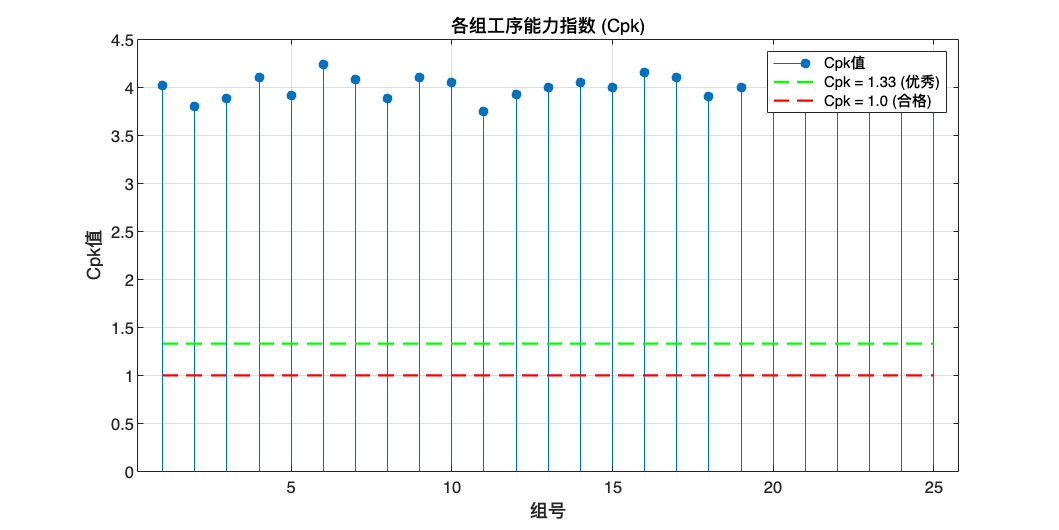


% 可视化Cpk分布
figure('Position', [100, 100, 800, 400]);
stem(1:num_groups, cpk_values, 'filled');
hold on;
plot([1, num_groups], [1.33, 1.33], 'g--', 'LineWidth', 1.5);
plot([1, num_groups], [1.0, 1.0], 'r--', 'LineWidth', 1.5);
title('各组工序能力指数 (Cpk)');
xlabel('组号');
ylabel('Cpk值');
grid on;
legend('Cpk值', 'Cpk = 1.33 (优秀)', 'Cpk = 1.0 (合格)');
hold off;

### 五、产品过程控制（使用Shewhart控制图进行SPC过程）

计算均值控制图和标准差控制图，并使用八大规则进行判断产品生产过程是否可控：

*    规则1：控制图上有一个点(对应某个批次数据)位于控制限以外；*

*    规则2：连续9个点落在中心线同一侧；*

*    规则3：连续6个点递增或者递减；*

*    规则4：连续14个点交替上下；*

*    规则5：连续3个点中有2个点落在中心线同侧的B区以外；*

*    规则6：连续5个点中有4个点落在中心线同侧的C区以外；*

*    规则7：连续15个点落在中心线两侧的C区；*

*    规则8：连续8个点落在中心线两侧且无一点在C区以内。*

上述规则适应于均值控制图和方差控制图，最终目的是识别产品生产过程是否，仅仅受到了随机因素的影响。

% 初始化参数
num_groups = size(noisy_data, 1);
samples_per_group = size(noisy_data, 2);
sample_means = zeros(num_groups, 1); % 样本均值
sample_stds = zeros(num_groups, 1); % 样本标准差

% 计算每组均值和标准差
for i = 1:num_groups
    sample_means(i) = mean(noisy_data(i, :));
    sample_stds(i) = std(noisy_data(i, :));
end

% 计算控制图参数
grand_mean = mean(sample_means); % 总均值
avg_std = mean(sample_stds); % 平均标准差

% 控制图常数（n=10）
A3 = 0.975; % X-bar chart constant
B3 = 0.284; % S chart lower constant
B4 = 1.716; % S chart upper constant

% X-bar chart 控制限
UCL_xbar = grand_mean + A3 * avg_std;
LCL_xbar = grand_mean - A3 * avg_std;

% S chart 控制限
UCL_s = B4 * avg_std;
LCL_s = B3 * avg_std;

% 应用八大规则
rule_violations_xbar = cell(num_groups, 1);
rule_violations_s = cell(num_groups, 1);
sigma_xbar = (UCL_xbar - grand_mean) / 3; % 1-sigma for X-bar chart
sigma_s = (UCL_s - avg_std) / 3; % 1-sigma for S chart

for i = 1:num_groups
    violations_xbar = '';
    violations_s = '';
    
    % Rule 1: One point beyond 3-sigma limits
    if sample_means(i) > UCL_xbar || sample_means(i) < LCL_xbar
        violations_xbar = [violations_xbar 'Rule 1; '];
    end
    if sample_stds(i) > UCL_s || sample_stds(i) < LCL_s
        violations_s = [violations_s 'Rule 1; '];
    end
    
    % Rule 2: Nine points in a row on same side of centerline
    if i >= 9
        if all(sample_means(i-8:i) > grand_mean) || all(sample_means(i-8:i) < grand_mean)
            violations_xbar = [violations_xbar 'Rule 2; '];
        end
        if all(sample_stds(i-8:i) > avg_std) || all(sample_stds(i-8:i) < avg_std)
            violations_s = [violations_s 'Rule 2; '];
        end
    end
    
    % Rule 3: Six points in a row steadily increasing or decreasing
    if i >= 6
        diffs = diff(sample_means(i-5:i));
        if all(diffs > 0) || all(diffs < 0)
            violations_xbar = [violations_xbar 'Rule 3; '];
        end
        diffs_s = diff(sample_stds(i-5:i));
        if all(diffs_s > 0) || all(diffs_s < 0)
            violations_s = [violations_s 'Rule 3; '];
        end
    end
    
    % Rule 4: Fourteen points in a row alternating up and down
    if i >= 14
        signs = sign(diff(sample_means(i-13:i)));
        if all(abs(diff(signs)) == 2)
            violations_xbar = [violations_xbar 'Rule 4; '];
        end
        signs_s = sign(diff(sample_stds(i-13:i)));
        if all(abs(diff(signs_s)) == 2)
            violations_s = [violations_s 'Rule 4; '];
        end
    end
    
    % Rule 5: Two out of three points beyond 2-sigma
    if i >= 3
        recent_means = sample_means(i-2:i);
        if sum(recent_means > grand_mean + 2*sigma_xbar | recent_means < grand_mean - 2*sigma_xbar) >= 2
            violations_xbar = [violations_xbar 'Rule 5; '];
        end
        recent_stds = sample_stds(i-2:i);
        if sum(recent_stds > avg_std + 2*sigma_s | recent_stds < avg_std - 2*sigma_s) >= 2
            violations_s = [violations_s 'Rule 5; '];
        end
    end
    
    % Rule 6: Four out of five points beyond 1-sigma
    if i >= 5
        recent_means = sample_means(i-4:i);
        if sum(recent_means > grand_mean + sigma_xbar | recent_means < grand_mean - sigma_xbar) >= 4
            violations_xbar = [violations_xbar 'Rule 6; '];
        end
        recent_stds = sample_stds(i-4:i);
        if sum(recent_stds > avg_std + sigma_s | recent_stds < avg_std - sigma_s) >= 4
            violations_s = [violations_s 'Rule 6; '];
        end
    end
    
    % Rule 7: Fifteen points in a row within 1-sigma
    if i >= 15
        if all(abs(sample_means(i-14:i) - grand_mean) < sigma_xbar)
            violations_xbar = [violations_xbar 'Rule 7; '];
        end
        if all(abs(sample_stds(i-14:i) - avg_std) < sigma_s)
            violations_s = [violations_s 'Rule 7; '];
        end
    end
    
    % Rule 8: Eight points in a row beyond 1-sigma (on both sides)
    if i >= 8
        if all(abs(sample_means(i-7:i) - grand_mean) > sigma_xbar)
            violations_xbar = [violations_xbar 'Rule 8; '];
        end
        if all(abs(sample_stds(i-7:i) - avg_std) > sigma_s)
            violations_s = [violations_s 'Rule 8; '];
        end
    end
    
    rule_violations_xbar{i} = violations_xbar;
    rule_violations_s{i} = violations_s;
end

% 创建结果表格
stats_table = table((1:num_groups)', sample_means, sample_stds, rule_violations_xbar, rule_violations_s, ...
    'VariableNames', {'组号', '样本均值', '样本标准差', 'Xbar_违规', 'S_违规'});

% 显示结果
disp('控制图分析结果：');

控制图分析结果：


disp(stats_table);

    组号    样本均值    样本标准差     Xbar_违规         S_违规   
    ____    _______    _________    ____________    ____________

      1     79.917      5.8154      {0×0 char  }    {0×0 char  }
      2     80.051      6.1324      {0×0 char  }    {0×0 char  }
      3     79.862      6.0225      {0×0 char  }    {0×0 char  }
      4     79.608      5.7247      {0×0 char  }    {0×0 char  }
      5     79.743      5.9923      {0×0 char  }    {0×0 char  }
      6     80.557      5.4667      {0×0 char  }    {0×0 char  }
      7     79.602      5.7477      {0×0 char  }    {0×0 char  }
      8     79.678       6.045      {0×0 char  }    {0×0 char  }
      9     79.921      5.6926      {0×0 char  }    {0×0 char  }
     10     79.999      5.7704      {0×0 char  }    {0×0 char  }
     11     80.141      6.2083      {0×0 char  }    {0×0 char  }
     12     80.448      5.9138      {'Rule 3; '}    {0×0 char  }
     13     79.566      5.8816      {0×0 char  }    {0×0 char  }
     14     80.039      5.7663      {


% 总结违规情况
out_of_control_xbar = sum(~cellfun(@isempty, rule_violations_xbar));
out_of_control_s = sum(~cellfun(@isempty, rule_violations_s));
fprintf('\n总结：\n');


总结：


fprintf('X-bar图：%d 组违反控制规则，表明过程均值可能失控。\n', out_of_control_xbar);

X-bar图：12 组违反控制规则，表明过程均值可能失控。


fprintf('S图：%d 组违反控制规则，表明过程变异性可能失控。\n', out_of_control_s);

S图：11 组违反控制规则，表明过程变异性可能失控。


if out_of_control_xbar == 0 && out_of_control_s == 0
    fprintf('过程受控，无显著非随机模式。\n');
else
    fprintf('过程可能失控，需调查违规原因（如设备、操作或环境变化）。\n');
end

过程可能失控，需调查违规原因（如设备、操作或环境变化）。


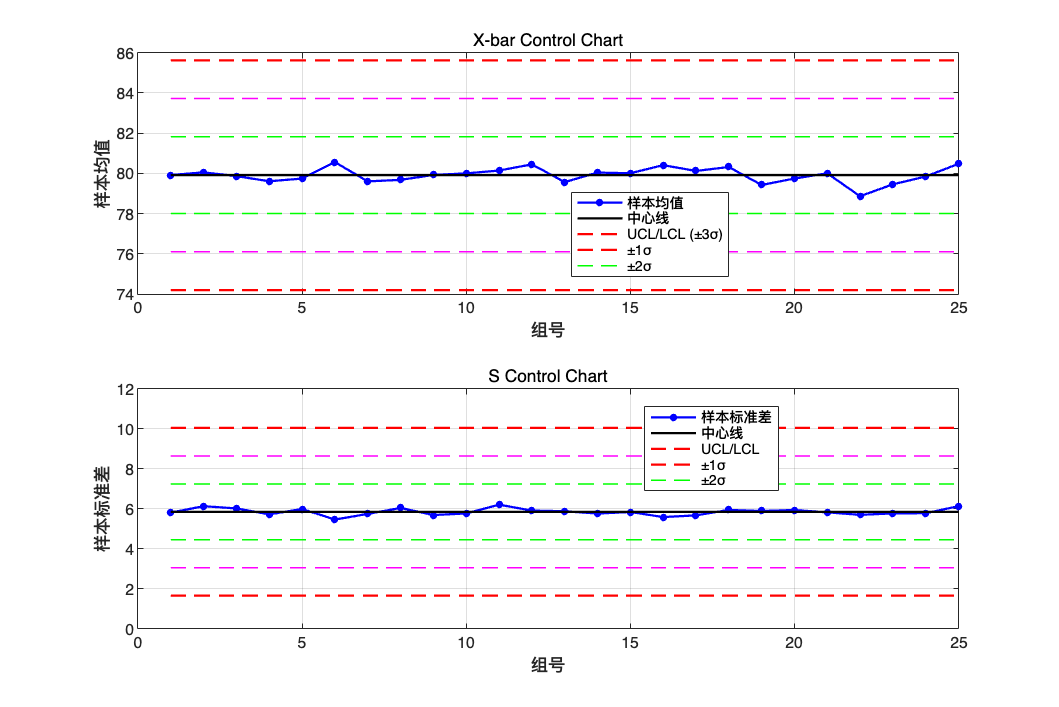


% 可视化控制图
figure('Position', [100, 100, 1200, 800]);

% X-bar Chart
subplot(2, 1, 1);
plot(1:num_groups, sample_means, 'b.-', 'LineWidth', 1.5, 'MarkerSize', 15);
hold on;
plot([1, num_groups], [grand_mean, grand_mean], 'k-', 'LineWidth', 1.5);
plot([1, num_groups], [UCL_xbar, UCL_xbar], 'r--', 'LineWidth', 1.5);
plot([1, num_groups], [LCL_xbar, LCL_xbar], 'r--', 'LineWidth', 1.5);
% 1-sigma and 2-sigma lines
plot([1, num_groups], [grand_mean + sigma_xbar, grand_mean + sigma_xbar], 'g--', 'LineWidth', 1);
plot([1, num_groups], [grand_mean - sigma_xbar, grand_mean - sigma_xbar], 'g--', 'LineWidth', 1);
plot([1, num_groups], [grand_mean + 2*sigma_xbar, grand_mean + 2*sigma_xbar], 'm--', 'LineWidth', 1);
plot([1, num_groups], [grand_mean - 2*sigma_xbar, grand_mean - 2*sigma_xbar], 'm--', 'LineWidth', 1);
title('X-bar Control Chart');
xlabel('组号');
ylabel('样本均值');
grid on;
legend('样本均值', '中心线', 'UCL/LCL (±3σ)', '±1σ', '±2σ', 'Location', 'Best');
hold off;

% S Chart
subplot(2, 1, 2);
plot(1:num_groups, sample_stds, 'b.-', 'LineWidth', 1.5, 'MarkerSize', 15);
hold on;
plot([1, num_groups], [avg_std, avg_std], 'k-', 'LineWidth', 1.5);
plot([1, num_groups], [UCL_s, UCL_s], 'r--', 'LineWidth', 1.5);
plot([1, num_groups], [LCL_s, LCL_s], 'r--', 'LineWidth', 1.5);
% 1-sigma and 2-sigma lines
plot([1, num_groups], [avg_std + sigma_s, avg_std + sigma_s], 'g--', 'LineWidth', 1);
plot([1, num_groups], [avg_std - sigma_s, avg_std - sigma_s], 'g--', 'LineWidth', 1);
plot([1, num_groups], [avg_std + 2*sigma_s, avg_std + 2*sigma_s], 'm--', 'LineWidth', 1);
plot([1, num_groups], [avg_std - 2*sigma_s, avg_std - 2*sigma_s], 'm--', 'LineWidth', 1);
title('S Control Chart');
xlabel('组号');
ylabel('样本标准差');
grid on;
legend('样本标准差', '中心线', 'UCL/LCL', '±1σ', '±2σ', 'Location', 'Best');
hold off;